# PROCESS CONTROL ASSIGNMENT 2

Name: NSENGUMUKIZA IRENE

MATRIC N0.: G2303789D

# LQR applied to aircraft

**(i) Design \quad 3 LQR \quad controllers for a fixed**$ $\gamma=0.01$ \quad and \quad $\rho=0.1,10,100$.$

gamma = 1e-2; 
rhos = [1e-1, 10, 1e2];
figure;
hold on;
for rho = rhos
A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
G = [1 0 0; 0, gamma*1, 0];
H = [0; 0];
Q = G' * G;
R = H'* H + rho;
N = G'* H;
[K, P, poles] = lqr(A, B, Q, R, N);
GO = ss(A, B, K, 0);
[GainMargin, PhaseMargin, GainCrossOverFreq, PhaseCrossOverFreq] = margin(GO);
sprintf('rho = %d and gamma = %d', rho, gamma)
disp('------------------------------------')
disp(PhaseMargin)
bode(GO)
end

ans = 'rho = 1.000000e-01 and gamma = 1.000000e-02'

------------------------------------


   66.6468



ans = 'rho = 10 and gamma = 1.000000e-02'

------------------------------------


   70.2300



ans = 'rho = 100 and gamma = 1.000000e-02'

------------------------------------


   74.9383



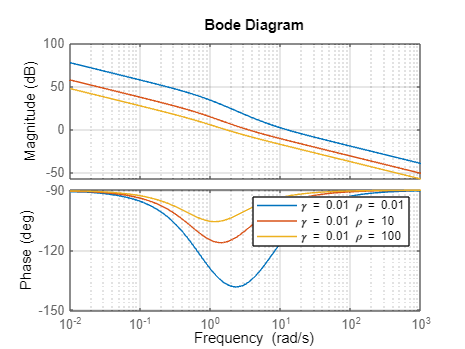

grid on;
hold off;
legend('\gamma = 0.01 \rho = 0.01', '\gamma = 0.01 \rho = 10', '\gamma = 0.01 \rho = 100')

**(ii). Design 3 LQR controllers for a fixed **$$\rho=0.01$ and $\gamma=0.01,0.1,1$$

rho = 1e-2; % Example values for gamma
gamma = [1e-2, 0.1, 1]; % Example values for rho
figure;
hold on;
for gam = gamma
A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
G = [1 0 0; 0, gam*1, 0];
H = [0; 0];
Q = G' * G;
R = H'* H + rho;
N = G'* H;
[K2, P2, poles2] = lqr(A, B, Q, R, N);
sprintf('rho = %d and gamma = %d', rho, gam)
disp('------------------------------------')
GO = ss(A, B, K2, 0);
[GainMargin, PhaseMargin, GainCrossOverFreq, PhaseCrossOverFreq] = margin(GO);
disp('Phase margin: ')
disp(PhaseMargin)
disp('------------------------------------')
bode(GO);
% step(GO);
end

ans = 'rho = 1.000000e-02 and gamma = 1.000000e-02'

------------------------------------


Phase margin: 


   65.7652



------------------------------------


ans = 'rho = 1.000000e-02 and gamma = 1.000000e-01'

------------------------------------


Phase margin: 


   74.3118



------------------------------------


ans = 'rho = 1.000000e-02 and gamma = 1'

------------------------------------


Phase margin: 


   72.7870



------------------------------------


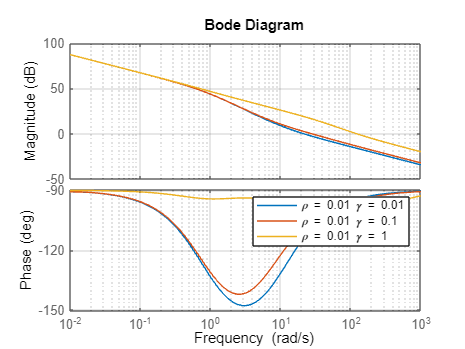

grid on;
hold off;
legend('\rho = 0.01 \gamma = 0.01', '\rho = 0.01 \gamma = 0.1', '\rho = 0.01 \gamma = 1')

**(iii) Determine the phase margins for the LQR controllers designed in Part 2(a)(i)and (ii).**

for each controller I used to compute phase margin at design point since I was using loop to iterate over them, the easiest way was to calculate phase margin of each controller at that point of designing.

**For the controllers designed in part 1**


$$\rho = 0.1 \quad \gamma = 0.01 \quad Phase -margin= 66.6468 \degree \\
\rho = 10 \quad \gamma = 0.01 \quad Phase -margin= 70.230 \degree \\
\rho = 100 \quad \gamma = 0.01 \quad Phase -margin= 74.9383 \degree \\
$$


**Effect of increasing **$$\rho$$

Increasing $$\rho$$ With $$\gamma$$ held constant at 0.01 leads to an increase in the phase margin. This indicates that increasing the weight on the state error relative to the control effort can make the system more robust to phase changes, as a higher phase margin indicates a larger buffer before the system reaches instability.

**For controllers designed in part 2**


$$\rho = 0.01 \quad \gamma = 0.01 \quad Phase -margin= 65.7652 \degree \\
\rho = 0.01 \quad \gamma = 0.1 \quad Phase -margin= 74.3118 \degree \\
\rho = 0.01 \quad \gamma = 1 \quad Phase -margin= 72.7870 \degree \\$$


**Effect of increasing **$$\gamma$$

Initially increasing $$\gamma$$ from 0.01 to 0.1 increases the phase margin, but further increasing $$\gamma$$ to 1 results in a slight decrease in the phase margin. This suggests that there might be an optimal range for 

$$\gamma$$ that maximizes the phase margin. This behavior is typical as tuning parameters may have non-linear effects on system stability metrics.

## Nyquist plot

`(i) Select `$$ Q = I_{2 \times 2}, R = 1, \rho = 0.1, \gamma = 1$$`. Plot the Nyquist plot of the loop transfer function`

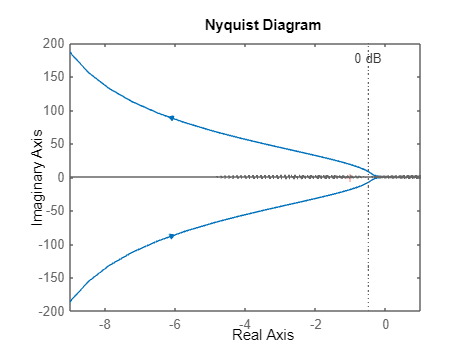

gamma = 1; % Example values for gamma
rho = 1e-1; % Example values for rho

A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
G = [1 0 0; 0, gamma*1, 0];
H = [0; 0];
Q = G' * G;
R = H'* H + rho;
N = G'* H;
K = lqr(A, B, Q, R, N);
GO = ss(A, B, K, 0);
figure;
nyquist(GO);
grid on;

`(ii) Under state feedback u = -Kx, the closed-loop dynamics are given by`


$$\dot{x} = (A - BK)x$$


`and the closed-loop poles are the eigenvalues of `$A - BK$`. compute a state feedback gain matrix `$K$` that assigns these poles to any locations. closed loop poles `$p = -1, -2, -3$**.**

A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];

% Define the desired closed-loop poles
p = [-1, -2, -3];

% Compute the state feedback gain matrix K using the place function
K = place(A, B, p)

K =    -0.0060   -0.0065   -0.8975


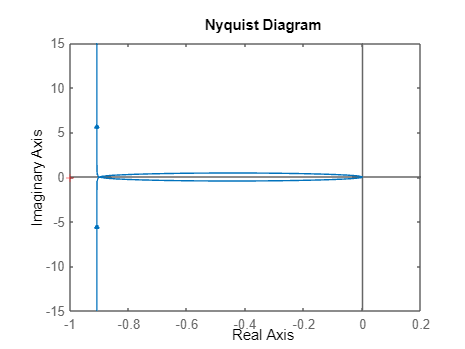

GO = ss(A, B, K, 0);
figure;
nyquist(GO);

**(iii) Compare the Nyquist plots obtained in (i) and (ii) in terms of whether these plots enter within a circle of radius 1 centered at -1. What can you conclude about the robustness of the 2 design methods against multiplicative uncertainty?**

The Nyquist plots for two control design methods were examined for robustness against multiplicative uncertainty by observing their behavior around a circle of radius 1 centered at -1 in the complex plane. Both plots avoided encircling the critical point, indicative of stable closed-loop systems. The first design method's Nyquist plot shows a conservative approach with a significant margin from the critical stability boundary. In contrast, the second method's plot, though more expansive, similarly does not intersect with the defined circle, suggesting an adequate stability margin.

Neither design's Nyquist plot enters the critical circle, pointing towards an inherent robustness to uncertainties that could perturb the system's poles within this region. While this suggests that both methods offer stable control strategies resistant to certain levels of uncertainty, a full assessment of robustness would require additional analysis, such as evaluating gain and phase margins, transient responses, and overall system performance objectives.

## Step Response

(i) Plot on the same graph, the step responses to roll angle setpoint command of  r = 1  rad for the 3 LQR state feedback controllers designed in Part 2(a) (i) for $\rho$ = 0.1, 10, 100  and $\gamma = 0.01$

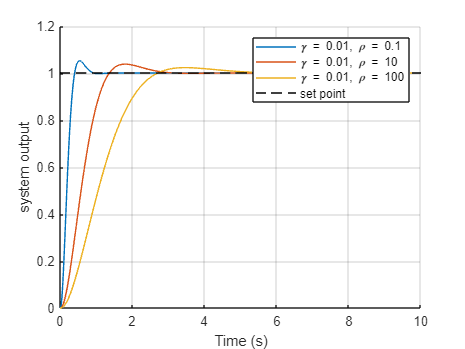

A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
gamma = 1e-2; % Fixed value for gamma
rhos = [1e-1, 1e1, 1e2]; % Iterating over these values for rho
G = [1 0 0; 0, gamma, 0];
H = [0; 0];
Q = G' * G;

% Define the reference set point
r = [1; 0; 0]; % Reference for the first state

% Simulation parameters
dt = 0.01; % Time step (s)
T = 10; % Total simulation time (s)
time = 0:dt:T; % Time vector

figure;
hold on;

% Iterate over the different values of rho
for idx = 1:length(rhos)
    R = rhos(idx); % Use the current rho value for R

    % Solve for the LQR gain matrix K
    [K, ~, ~] = lqr(A, B, Q, R);
    % Initial conditions
    x = zeros(3,1); % Initialize state

    % Preallocate state history for plotting
    x_history = zeros(3, length(time));

    % Closed-loop simulation
    for i = 1:length(time)
        % Control law with reference tracking
        u = -K*(x - r);

        % System dynamics
        x_dot = A*x + B*u;

        % Euler integration for state update
        x = x + x_dot * dt;

        % Store state history
        x_history(:, i) = x;
    end

    % Plotting for the current rho value
    plot(time, x_history(1,:), 'DisplayName', ['\gamma = ', num2str(gamma), ', \rho = ', num2str(rhos(idx))]);
end

% Plot reference line
plot(time, r(1)*ones(size(time)), 'k--', 'DisplayName', 'set point');

% Enhance plot
% title('Open-loop gain for several values of \rho and \gamma = 0.01');
xlabel('Time (s)');
ylabel('system output');
legend('show');
grid on;
hold off;

`(ii) Plot on the same graph, the step responses to roll angle setpoint command of r=1 rad for the 3 LQR state feedback controllers designed in Part 2(a) (ii) for `$\gamma$` = 0.01, 0.1, 1.`

% Define system matrices
A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
rho = 1e-2; 
gamma = [1e-2, 1e-1, 1]; 
R = rho; 
r = [1; 0; 0];

% Simulation parameters
dt = 0.01; % Time step (s)
T = 6; % Total simulation time (s)
time = 0:dt:T; % Time vector

% Preallocate figure for plots
figure;
hold on;

% Iterate over the different values of rho
for idx = 1:length(gamma)
    G = [1 0 0; 0, gamma(idx), 0];
    Q = G' * G;
    % Solve for the LQR gain matrix K
    [K, ~, ~] = lqr(A, B, Q, R);

    fprintf("%d : K: ", idx);
    disp(K)
    disp('________________________________________')
    % Initial conditions
    x = zeros(3,1); % Initialize state

    % Preallocate state history for plotting
    x_history = zeros(3, length(time));

    % Closed-loop simulation
    for i = 1:length(time)
        % Control law with reference tracking
        u = -K*(x - r);

        % System dynamics
        x_dot = A*x + B*u;

        % Euler integration for state update
        x = x + x_dot * dt;

        % Store state history
        x_history(:, i) = x;
    end

    % Plotting for the current rho value
    plot(time, x_history(1,:), 'DisplayName', ['\gamma = ', num2str(gamma(idx)), ', \rho = ', num2str(R)]);
end

1 : K: 

  -10.0000   -1.1264    0.3788



________________________________________


2 : K: 

  -10.0000   -1.5184    0.4882



________________________________________


3 : K: 

  -10.0000  -10.0186    2.0025



________________________________________


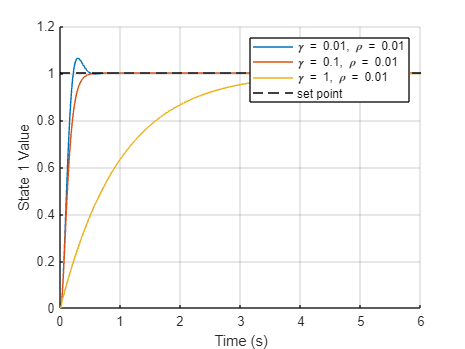


% Plot reference line
plot(time, r(1)*ones(size(time)), 'k--', 'DisplayName', 'set point');

% Enhance plot
% title('State 1 Trajectories with LQR Control and Reference Tracking for Different \rho');
xlabel('Time (s)');
ylabel('State 1 Value');
legend('show');
grid on;
hold off;

**(iii) Compare the effect of the step responses (speed and overshoot) for variations in **$\rho$**  and **$\gamma$

**For varying **$$\rho$$

**Low** 

$$\rho$$ (0.01): The response quickly rises to the setpoint with some initial overshoot and oscillations, indicating a potentially more aggressive control action with less weight on control effort (since $$\rho$$ is in the denominator of the control weight in the LQR cost function). 

**Medium**

$$\rho$$ (10): The response is slower, with no overshoot, showing a more conservative control action where both state errors and control effort are more balanced.

**High **

$$\rho$$ (100): The response is the slowest, with the least aggressive control action, indicating a high weight on minimizing control effort compared to state errors.

**For fixed **$$\rho$$

**Low** $$\gamma$$ (0.01): Similar to the low 

$$\rho$$ case, the system responds quickly and with an initial overshoot, indicating an aggressive control action that prioritizes state error over control effort.

**Medium** 

$$\gamma$$ (0.1): The response is slower and with no overshoot, suggesting a balance between state error and control effort.

**High **

$$\gamma$$ (1): The response is very slow and the least aggressive, prioritizing control effort significantly over state error minimization.

**Comparative Analysis**

Speed of Response

 Lower values of $$\rho$ $ and $$\gamma$$ leads to faster system responses. This is because a lower value in the LQR cost function denominator implies less emphasis on the control effort, allowing the controller to act more aggressively to minimize state errors. 

Overshoot

Lower values of $$\rho$$ and $$\gamma$$ results in more overshoot, which is typical for more aggressive control strategies. Higher values tend to suppress overshoot, indicating a more cautious approach to control action.

Stability and Robustness

While not directly observable from these plots, systems with higher values of 

$$\rho$$ and $$\gamma$$ are likely to be more robust to disturbances and model uncertainties since they apply control more gently, avoiding sharp reactions that could be destabilizing in the presence of real-world uncertainties.

Control Effort

A higher value of $$\rho$$ and $$\gamma$$ implies a controller that puts more emphasis on reducing control effort, which can be important for energy savings or when dealing with actuator limitations.

## Set-Point Tracking

% Define system matrices

A = [0 1 0; 0 -0.875 20; 0 0 -50];
B = [0; 0; 50];
C = [1 0 0;0 1 0];
Q = C' * C;
R = 1; % As provided from the previous calculations

% Compute the LQR gain matrix K
[K, ~, ~] = lqr(A, B, Q, R);

r = 1%[1; 1; 1]; 

r = 1


% Simulation parameters
dt = 0.01; % Time step (s)
T = 10; % Total simulation time (s)
time = 0:dt:T; % Time vector
x_history = zeros(3, length(time));
% Preallocate figure for plots
figure;
hold on;

x = zeros(3,1); % Initialize state to match the system dimension

for i = 1:length(time)
    % Control law with reference tracking and pre-compensatory gain
    u = -K * (x - r);
    % System dynamics
    Ccl = [1 0 0];
    Bcl = [1; 0; 0];
    e = -1 / (Ccl*inv(A - B*K)*Bcl);
    % x_dot = A * x + B * u + Bcl'*r*e;
    x_dot = (A - B*K)*x + Bcl*r*e;
    % Euler integration for state update
    x = x + x_dot * dt;
    disp('X: COMPUTED')
    disp(x)

    % % Store state history
    x_history(:, i) = x;
end

X: COMPUTED


    0.0094
         0
         0



X: COMPUTED


    0.0187
         0
   -0.0047



X: COMPUTED


    0.0281
   -0.0009
   -0.0109



X: COMPUTED


    0.0375
   -0.0031
   -0.0172



X: COMPUTED


    0.0468
   -0.0065
   -0.0228



X: COMPUTED


    0.0561
   -0.0110
   -0.0276



X: COMPUTED


    0.0654
   -0.0164
   -0.0316



X: COMPUTED


    0.0746
   -0.0226
   -0.0348



X: COMPUTED


    0.0838
   -0.0294
   -0.0373



X: COMPUTED


    0.0928
   -0.0366
   -0.0393



X: COMPUTED


    0.1018
   -0.0441
   -0.0409



X: COMPUTED


    0.1108
   -0.0519
   -0.0421



X: COMPUTED


    0.1196
   -0.0599
   -0.0430



X: COMPUTED


    0.1284
   -0.0680
   -0.0438



X: COMPUTED


    0.1371
   -0.0761
   -0.0443



X: COMPUTED


    0.1457
   -0.0843
   -0.0447



X: COMPUTED


    0.1542
   -0.0925
   -0.0450



X: COMPUTED


    0.1627
   -0.1007
   -0.0453



X: COMPUTED


    0.1711
   -0.1089
   -0.0454



X: COMPUTED


    0.1793
   -0.1170
   -0.0456



X: COMPUTED


    0.1875
   -0.1251
   -0.0456



X: COMPUTED


    0.1957
   -0.1331
   -0.0457



X: COMPUTED


    0.2037
   -0.1411
   -0.0457



X: COMPUTED


    0.2117
   -0.1490
   -0.0457



X: COMPUTED


    0.2196
   -0.1569
   -0.0457



X: COMPUTED


    0.2274
   -0.1646
   -0.0457



X: COMPUTED


    0.2351
   -0.1723
   -0.0457



X: COMPUTED


    0.2427
   -0.1800
   -0.0457



X: COMPUTED


    0.2503
   -0.1875
   -0.0456



X: COMPUTED


    0.2578
   -0.1950
   -0.0456



X: COMPUTED


    0.2652
   -0.2024
   -0.0456



X: COMPUTED


    0.2726
   -0.2098
   -0.0455



X: COMPUTED


    0.2799
   -0.2171
   -0.0455



X: COMPUTED


    0.2871
   -0.2243
   -0.0455



X: COMPUTED


    0.2942
   -0.2314
   -0.0454



X: COMPUTED


    0.3013
   -0.2384
   -0.0454



X: COMPUTED


    0.3082
   -0.2454
   -0.0453



X: COMPUTED


    0.3152
   -0.2524
   -0.0453



X: COMPUTED


    0.3220
   -0.2592
   -0.0453



X: COMPUTED


    0.3288
   -0.2660
   -0.0452



X: COMPUTED


    0.3355
   -0.2727
   -0.0452



X: COMPUTED


    0.3422
   -0.2794
   -0.0451



X: COMPUTED


    0.3487
   -0.2859
   -0.0451



X: COMPUTED


    0.3553
   -0.2924
   -0.0450



X: COMPUTED


    0.3617
   -0.2989
   -0.0450



X: COMPUTED


    0.3681
   -0.3053
   -0.0450



X: COMPUTED


    0.3744
   -0.3116
   -0.0449



X: COMPUTED


    0.3807
   -0.3179
   -0.0449



X: COMPUTED


    0.3869
   -0.3241
   -0.0449



X: COMPUTED


    0.3930
   -0.3302
   -0.0448



X: COMPUTED


    0.3991
   -0.3363
   -0.0448



X: COMPUTED


    0.4051
   -0.3423
   -0.0447



X: COMPUTED


    0.4110
   -0.3482
   -0.0447



X: COMPUTED


    0.4169
   -0.3541
   -0.0447



X: COMPUTED


    0.4228
   -0.3600
   -0.0446



X: COMPUTED


    0.4285
   -0.3657
   -0.0446



X: COMPUTED


    0.4342
   -0.3715
   -0.0446



X: COMPUTED


    0.4399
   -0.3771
   -0.0445



X: COMPUTED


    0.4455
   -0.3827
   -0.0445



X: COMPUTED


    0.4511
   -0.3883
   -0.0445



X: COMPUTED


    0.4565
   -0.3938
   -0.0444



X: COMPUTED


    0.4620
   -0.3992
   -0.0444



X: COMPUTED


    0.4674
   -0.4046
   -0.0443



X: COMPUTED


    0.4727
   -0.4099
   -0.0443



X: COMPUTED


    0.4780
   -0.4152
   -0.0443



X: COMPUTED


    0.4832
   -0.4204
   -0.0442



X: COMPUTED


    0.4884
   -0.4256
   -0.0442



X: COMPUTED


    0.4935
   -0.4307
   -0.0442



X: COMPUTED


    0.4985
   -0.4358
   -0.0442



X: COMPUTED


    0.5036
   -0.4408
   -0.0441



X: COMPUTED


    0.5085
   -0.4458
   -0.0441



X: COMPUTED


    0.5134
   -0.4507
   -0.0441



X: COMPUTED


    0.5183
   -0.4555
   -0.0440



X: COMPUTED


    0.5231
   -0.4604
   -0.0440



X: COMPUTED


    0.5279
   -0.4651
   -0.0440



X: COMPUTED


    0.5326
   -0.4699
   -0.0439



X: COMPUTED


    0.5373
   -0.4745
   -0.0439



X: COMPUTED


    0.5419
   -0.4792
   -0.0439



X: COMPUTED


    0.5465
   -0.4838
   -0.0439



X: COMPUTED


    0.5510
   -0.4883
   -0.0438



X: COMPUTED


    0.5555
   -0.4928
   -0.0438



X: COMPUTED


    0.5600
   -0.4972
   -0.0438



X: COMPUTED


    0.5644
   -0.5016
   -0.0437



X: COMPUTED


    0.5687
   -0.5060
   -0.0437



X: COMPUTED


    0.5731
   -0.5103
   -0.0437



X: COMPUTED


    0.5773
   -0.5146
   -0.0437



X: COMPUTED


    0.5815
   -0.5188
   -0.0436



X: COMPUTED


    0.5857
   -0.5230
   -0.0436



X: COMPUTED


    0.5899
   -0.5271
   -0.0436



X: COMPUTED


    0.5940
   -0.5312
   -0.0436



X: COMPUTED


    0.5980
   -0.5353
   -0.0435



X: COMPUTED


    0.6021
   -0.5393
   -0.0435



X: COMPUTED


    0.6060
   -0.5433
   -0.0435



X: COMPUTED


    0.6100
   -0.5473
   -0.0435



X: COMPUTED


    0.6139
   -0.5512
   -0.0434



X: COMPUTED


    0.6177
   -0.5550
   -0.0434



X: COMPUTED


    0.6216
   -0.5588
   -0.0434



X: COMPUTED


    0.6254
   -0.5626
   -0.0434



X: COMPUTED


    0.6291
   -0.5664
   -0.0433



X: COMPUTED


    0.6328
   -0.5701
   -0.0433



X: COMPUTED


    0.6365
   -0.5738
   -0.0433



X: COMPUTED


    0.6401
   -0.5774
   -0.0433



X: COMPUTED


    0.6437
   -0.5810
   -0.0432



X: COMPUTED


    0.6473
   -0.5846
   -0.0432



X: COMPUTED


    0.6508
   -0.5881
   -0.0432



X: COMPUTED


    0.6543
   -0.5916
   -0.0432



X: COMPUTED


    0.6578
   -0.5950
   -0.0432



X: COMPUTED


    0.6612
   -0.5985
   -0.0431



X: COMPUTED


    0.6646
   -0.6019
   -0.0431



X: COMPUTED


    0.6679
   -0.6052
   -0.0431



X: COMPUTED


    0.6713
   -0.6085
   -0.0431



X: COMPUTED


    0.6745
   -0.6118
   -0.0430



X: COMPUTED


    0.6778
   -0.6151
   -0.0430



X: COMPUTED


    0.6810
   -0.6183
   -0.0430



X: COMPUTED


    0.6842
   -0.6215
   -0.0430



X: COMPUTED


    0.6874
   -0.6247
   -0.0430



X: COMPUTED


    0.6905
   -0.6278
   -0.0429



X: COMPUTED


    0.6936
   -0.6309
   -0.0429



X: COMPUTED


    0.6967
   -0.6340
   -0.0429



X: COMPUTED


    0.6997
   -0.6370
   -0.0429



X: COMPUTED


    0.7027
   -0.6400
   -0.0429



X: COMPUTED


    0.7057
   -0.6430
   -0.0429



X: COMPUTED


    0.7086
   -0.6459
   -0.0428



X: COMPUTED


    0.7115
   -0.6488
   -0.0428



X: COMPUTED


    0.7144
   -0.6517
   -0.0428



X: COMPUTED


    0.7173
   -0.6546
   -0.0428



X: COMPUTED


    0.7201
   -0.6574
   -0.0428



X: COMPUTED


    0.7229
   -0.6602
   -0.0427



X: COMPUTED


    0.7257
   -0.6630
   -0.0427



X: COMPUTED


    0.7284
   -0.6657
   -0.0427



X: COMPUTED


    0.7311
   -0.6684
   -0.0427



X: COMPUTED


    0.7338
   -0.6711
   -0.0427



X: COMPUTED


    0.7365
   -0.6738
   -0.0427



X: COMPUTED


    0.7391
   -0.6764
   -0.0426



X: COMPUTED


    0.7417
   -0.6790
   -0.0426



X: COMPUTED


    0.7443
   -0.6816
   -0.0426



X: COMPUTED


    0.7469
   -0.6842
   -0.0426



X: COMPUTED


    0.7494
   -0.6867
   -0.0426



X: COMPUTED


    0.7519
   -0.6892
   -0.0426



X: COMPUTED


    0.7544
   -0.6917
   -0.0425



X: COMPUTED


    0.7568
   -0.6942
   -0.0425



X: COMPUTED


    0.7593
   -0.6966
   -0.0425



X: COMPUTED


    0.7617
   -0.6990
   -0.0425



X: COMPUTED


    0.7641
   -0.7014
   -0.0425



X: COMPUTED


    0.7664
   -0.7037
   -0.0425



X: COMPUTED


    0.7688
   -0.7061
   -0.0425



X: COMPUTED


    0.7711
   -0.7084
   -0.0424



X: COMPUTED


    0.7734
   -0.7107
   -0.0424



X: COMPUTED


    0.7756
   -0.7130
   -0.0424



X: COMPUTED


    0.7779
   -0.7152
   -0.0424



X: COMPUTED


    0.7801
   -0.7174
   -0.0424



X: COMPUTED


    0.7823
   -0.7196
   -0.0424



X: COMPUTED


    0.7845
   -0.7218
   -0.0424



X: COMPUTED


    0.7866
   -0.7240
   -0.0423



X: COMPUTED


    0.7888
   -0.7261
   -0.0423



X: COMPUTED


    0.7909
   -0.7282
   -0.0423



X: COMPUTED


    0.7930
   -0.7303
   -0.0423



X: COMPUTED


    0.7950
   -0.7324
   -0.0423



X: COMPUTED


    0.7971
   -0.7344
   -0.0423



X: COMPUTED


    0.7991
   -0.7364
   -0.0423



X: COMPUTED


    0.8011
   -0.7385
   -0.0423



X: COMPUTED


    0.8031
   -0.7404
   -0.0422



X: COMPUTED


    0.8051
   -0.7424
   -0.0422



X: COMPUTED


    0.8070
   -0.7444
   -0.0422



X: COMPUTED


    0.8090
   -0.7463
   -0.0422



X: COMPUTED


    0.8109
   -0.7482
   -0.0422



X: COMPUTED


    0.8128
   -0.7501
   -0.0422



X: COMPUTED


    0.8147
   -0.7520
   -0.0422



X: COMPUTED


    0.8165
   -0.7538
   -0.0422



X: COMPUTED


    0.8183
   -0.7557
   -0.0421



X: COMPUTED


    0.8202
   -0.7575
   -0.0421



X: COMPUTED


    0.8220
   -0.7593
   -0.0421



X: COMPUTED


    0.8237
   -0.7611
   -0.0421



X: COMPUTED


    0.8255
   -0.7628
   -0.0421



X: COMPUTED


    0.8272
   -0.7646
   -0.0421



X: COMPUTED


    0.8290
   -0.7663
   -0.0421



X: COMPUTED


    0.8307
   -0.7680
   -0.0421



X: COMPUTED


    0.8324
   -0.7697
   -0.0421



X: COMPUTED


    0.8341
   -0.7714
   -0.0421



X: COMPUTED


    0.8357
   -0.7730
   -0.0420



X: COMPUTED


    0.8374
   -0.7747
   -0.0420



X: COMPUTED


    0.8390
   -0.7763
   -0.0420



X: COMPUTED


    0.8406
   -0.7779
   -0.0420



X: COMPUTED


    0.8422
   -0.7795
   -0.0420



X: COMPUTED


    0.8438
   -0.7811
   -0.0420



X: COMPUTED


    0.8453
   -0.7827
   -0.0420



X: COMPUTED


    0.8469
   -0.7842
   -0.0420



X: COMPUTED


    0.8484
   -0.7857
   -0.0420



X: COMPUTED


    0.8499
   -0.7873
   -0.0420



X: COMPUTED


    0.8514
   -0.7888
   -0.0419



X: COMPUTED


    0.8529
   -0.7903
   -0.0419



X: COMPUTED


    0.8544
   -0.7917
   -0.0419



X: COMPUTED


    0.8558
   -0.7932
   -0.0419



X: COMPUTED


    0.8573
   -0.7946
   -0.0419



X: COMPUTED


    0.8587
   -0.7961
   -0.0419



X: COMPUTED


    0.8601
   -0.7975
   -0.0419



X: COMPUTED


    0.8615
   -0.7989
   -0.0419



X: COMPUTED


    0.8629
   -0.8002
   -0.0419



X: COMPUTED


    0.8643
   -0.8016
   -0.0419



X: COMPUTED


    0.8656
   -0.8030
   -0.0419



X: COMPUTED


    0.8670
   -0.8043
   -0.0418



X: COMPUTED


    0.8683
   -0.8057
   -0.0418



X: COMPUTED


    0.8696
   -0.8070
   -0.0418



X: COMPUTED


    0.8709
   -0.8083
   -0.0418



X: COMPUTED


    0.8722
   -0.8096
   -0.0418



X: COMPUTED


    0.8735
   -0.8108
   -0.0418



X: COMPUTED


    0.8748
   -0.8121
   -0.0418



X: COMPUTED


    0.8760
   -0.8134
   -0.0418



X: COMPUTED


    0.8773
   -0.8146
   -0.0418



X: COMPUTED


    0.8785
   -0.8158
   -0.0418



X: COMPUTED


    0.8797
   -0.8171
   -0.0418



X: COMPUTED


    0.8809
   -0.8183
   -0.0418



X: COMPUTED


    0.8821
   -0.8194
   -0.0417



X: COMPUTED


    0.8833
   -0.8206
   -0.0417



X: COMPUTED


    0.8844
   -0.8218
   -0.0417



X: COMPUTED


    0.8856
   -0.8229
   -0.0417



X: COMPUTED


    0.8867
   -0.8241
   -0.0417



X: COMPUTED


    0.8879
   -0.8252
   -0.0417



X: COMPUTED


    0.8890
   -0.8263
   -0.0417



X: COMPUTED


    0.8901
   -0.8275
   -0.0417



X: COMPUTED


    0.8912
   -0.8286
   -0.0417



X: COMPUTED


    0.8923
   -0.8296
   -0.0417



X: COMPUTED


    0.8934
   -0.8307
   -0.0417



X: COMPUTED


    0.8944
   -0.8318
   -0.0417



X: COMPUTED


    0.8955
   -0.8328
   -0.0417



X: COMPUTED


    0.8965
   -0.8339
   -0.0417



X: COMPUTED


    0.8976
   -0.8349
   -0.0417



X: COMPUTED


    0.8986
   -0.8360
   -0.0416



X: COMPUTED


    0.8996
   -0.8370
   -0.0416



X: COMPUTED


    0.9006
   -0.8380
   -0.0416



X: COMPUTED


    0.9016
   -0.8390
   -0.0416



X: COMPUTED


    0.9026
   -0.8400
   -0.0416



X: COMPUTED


    0.9036
   -0.8409
   -0.0416



X: COMPUTED


    0.9045
   -0.8419
   -0.0416



X: COMPUTED


    0.9055
   -0.8428
   -0.0416



X: COMPUTED


    0.9064
   -0.8438
   -0.0416



X: COMPUTED


    0.9074
   -0.8447
   -0.0416



X: COMPUTED


    0.9083
   -0.8457
   -0.0416



X: COMPUTED


    0.9092
   -0.8466
   -0.0416



X: COMPUTED


    0.9101
   -0.8475
   -0.0416



X: COMPUTED


    0.9110
   -0.8484
   -0.0416



X: COMPUTED


    0.9119
   -0.8493
   -0.0416



X: COMPUTED


    0.9128
   -0.8502
   -0.0416



X: COMPUTED


    0.9137
   -0.8510
   -0.0416



X: COMPUTED


    0.9145
   -0.8519
   -0.0415



X: COMPUTED


    0.9154
   -0.8527
   -0.0415



X: COMPUTED


    0.9162
   -0.8536
   -0.0415



X: COMPUTED


    0.9171
   -0.8544
   -0.0415



X: COMPUTED


    0.9179
   -0.8553
   -0.0415



X: COMPUTED


    0.9187
   -0.8561
   -0.0415



X: COMPUTED


    0.9195
   -0.8569
   -0.0415



X: COMPUTED


    0.9203
   -0.8577
   -0.0415



X: COMPUTED


    0.9211
   -0.8585
   -0.0415



X: COMPUTED


    0.9219
   -0.8593
   -0.0415



X: COMPUTED


    0.9227
   -0.8601
   -0.0415



X: COMPUTED


    0.9235
   -0.8608
   -0.0415



X: COMPUTED


    0.9242
   -0.8616
   -0.0415



X: COMPUTED


    0.9250
   -0.8624
   -0.0415



X: COMPUTED


    0.9258
   -0.8631
   -0.0415



X: COMPUTED


    0.9265
   -0.8639
   -0.0415



X: COMPUTED


    0.9272
   -0.8646
   -0.0415



X: COMPUTED


    0.9280
   -0.8653
   -0.0415



X: COMPUTED


    0.9287
   -0.8660
   -0.0415



X: COMPUTED


    0.9294
   -0.8668
   -0.0415



X: COMPUTED


    0.9301
   -0.8675
   -0.0414



X: COMPUTED


    0.9308
   -0.8682
   -0.0414



X: COMPUTED


    0.9315
   -0.8689
   -0.0414



X: COMPUTED


    0.9322
   -0.8695
   -0.0414



X: COMPUTED


    0.9329
   -0.8702
   -0.0414



X: COMPUTED


    0.9335
   -0.8709
   -0.0414



X: COMPUTED


    0.9342
   -0.8716
   -0.0414



X: COMPUTED


    0.9348
   -0.8722
   -0.0414



X: COMPUTED


    0.9355
   -0.8729
   -0.0414



X: COMPUTED


    0.9361
   -0.8735
   -0.0414



X: COMPUTED


    0.9368
   -0.8741
   -0.0414



X: COMPUTED


    0.9374
   -0.8748
   -0.0414



X: COMPUTED


    0.9380
   -0.8754
   -0.0414



X: COMPUTED


    0.9387
   -0.8760
   -0.0414



X: COMPUTED


    0.9393
   -0.8766
   -0.0414



X: COMPUTED


    0.9399
   -0.8772
   -0.0414



X: COMPUTED


    0.9405
   -0.8778
   -0.0414



X: COMPUTED


    0.9411
   -0.8784
   -0.0414



X: COMPUTED


    0.9417
   -0.8790
   -0.0414



X: COMPUTED


    0.9423
   -0.8796
   -0.0414



X: COMPUTED


    0.9428
   -0.8802
   -0.0414



X: COMPUTED


    0.9434
   -0.8808
   -0.0414



X: COMPUTED


    0.9440
   -0.8813
   -0.0414



X: COMPUTED


    0.9445
   -0.8819
   -0.0414



X: COMPUTED


    0.9451
   -0.8824
   -0.0414



X: COMPUTED


    0.9456
   -0.8830
   -0.0414



X: COMPUTED


    0.9462
   -0.8835
   -0.0413



X: COMPUTED


    0.9467
   -0.8841
   -0.0413



X: COMPUTED


    0.9472
   -0.8846
   -0.0413



X: COMPUTED


    0.9478
   -0.8851
   -0.0413



X: COMPUTED


    0.9483
   -0.8857
   -0.0413



X: COMPUTED


    0.9488
   -0.8862
   -0.0413



X: COMPUTED


    0.9493
   -0.8867
   -0.0413



X: COMPUTED


    0.9498
   -0.8872
   -0.0413



X: COMPUTED


    0.9503
   -0.8877
   -0.0413



X: COMPUTED


    0.9508
   -0.8882
   -0.0413



X: COMPUTED


    0.9513
   -0.8887
   -0.0413



X: COMPUTED


    0.9518
   -0.8892
   -0.0413



X: COMPUTED


    0.9523
   -0.8897
   -0.0413



X: COMPUTED


    0.9528
   -0.8901
   -0.0413



X: COMPUTED


    0.9532
   -0.8906
   -0.0413



X: COMPUTED


    0.9537
   -0.8911
   -0.0413



X: COMPUTED


    0.9542
   -0.8915
   -0.0413



X: COMPUTED


    0.9546
   -0.8920
   -0.0413



X: COMPUTED


    0.9551
   -0.8925
   -0.0413



X: COMPUTED


    0.9555
   -0.8929
   -0.0413



X: COMPUTED


    0.9560
   -0.8933
   -0.0413



X: COMPUTED


    0.9564
   -0.8938
   -0.0413



X: COMPUTED


    0.9569
   -0.8942
   -0.0413



X: COMPUTED


    0.9573
   -0.8947
   -0.0413



X: COMPUTED


    0.9577
   -0.8951
   -0.0413



X: COMPUTED


    0.9581
   -0.8955
   -0.0413



X: COMPUTED


    0.9586
   -0.8959
   -0.0413



X: COMPUTED


    0.9590
   -0.8963
   -0.0413



X: COMPUTED


    0.9594
   -0.8968
   -0.0413



X: COMPUTED


    0.9598
   -0.8972
   -0.0413



X: COMPUTED


    0.9602
   -0.8976
   -0.0413



X: COMPUTED


    0.9606
   -0.8980
   -0.0413



X: COMPUTED


    0.9610
   -0.8984
   -0.0413



X: COMPUTED


    0.9614
   -0.8987
   -0.0413



X: COMPUTED


    0.9618
   -0.8991
   -0.0413



X: COMPUTED


    0.9621
   -0.8995
   -0.0412



X: COMPUTED


    0.9625
   -0.8999
   -0.0412



X: COMPUTED


    0.9629
   -0.9003
   -0.0412



X: COMPUTED


    0.9633
   -0.9006
   -0.0412



X: COMPUTED


    0.9636
   -0.9010
   -0.0412



X: COMPUTED


    0.9640
   -0.9014
   -0.0412



X: COMPUTED


    0.9644
   -0.9017
   -0.0412



X: COMPUTED


    0.9647
   -0.9021
   -0.0412



X: COMPUTED


    0.9651
   -0.9024
   -0.0412



X: COMPUTED


    0.9654
   -0.9028
   -0.0412



X: COMPUTED


    0.9658
   -0.9031
   -0.0412



X: COMPUTED


    0.9661
   -0.9035
   -0.0412



X: COMPUTED


    0.9664
   -0.9038
   -0.0412



X: COMPUTED


    0.9668
   -0.9042
   -0.0412



X: COMPUTED


    0.9671
   -0.9045
   -0.0412



X: COMPUTED


    0.9674
   -0.9048
   -0.0412



X: COMPUTED


    0.9678
   -0.9051
   -0.0412



X: COMPUTED


    0.9681
   -0.9055
   -0.0412



X: COMPUTED


    0.9684
   -0.9058
   -0.0412



X: COMPUTED


    0.9687
   -0.9061
   -0.0412



X: COMPUTED


    0.9690
   -0.9064
   -0.0412



X: COMPUTED


    0.9693
   -0.9067
   -0.0412



X: COMPUTED


    0.9697
   -0.9070
   -0.0412



X: COMPUTED


    0.9700
   -0.9073
   -0.0412



X: COMPUTED


    0.9703
   -0.9076
   -0.0412



X: COMPUTED


    0.9706
   -0.9079
   -0.0412



X: COMPUTED


    0.9709
   -0.9082
   -0.0412



X: COMPUTED


    0.9711
   -0.9085
   -0.0412



X: COMPUTED


    0.9714
   -0.9088
   -0.0412



X: COMPUTED


    0.9717
   -0.9091
   -0.0412



X: COMPUTED


    0.9720
   -0.9094
   -0.0412



X: COMPUTED


    0.9723
   -0.9097
   -0.0412



X: COMPUTED


    0.9726
   -0.9099
   -0.0412



X: COMPUTED


    0.9728
   -0.9102
   -0.0412



X: COMPUTED


    0.9731
   -0.9105
   -0.0412



X: COMPUTED


    0.9734
   -0.9107
   -0.0412



X: COMPUTED


    0.9736
   -0.9110
   -0.0412



X: COMPUTED


    0.9739
   -0.9113
   -0.0412



X: COMPUTED


    0.9742
   -0.9115
   -0.0412



X: COMPUTED


    0.9744
   -0.9118
   -0.0412



X: COMPUTED


    0.9747
   -0.9121
   -0.0412



X: COMPUTED


    0.9749
   -0.9123
   -0.0412



X: COMPUTED


    0.9752
   -0.9126
   -0.0412



X: COMPUTED


    0.9754
   -0.9128
   -0.0412



X: COMPUTED


    0.9757
   -0.9130
   -0.0412



X: COMPUTED


    0.9759
   -0.9133
   -0.0412



X: COMPUTED


    0.9762
   -0.9135
   -0.0412



X: COMPUTED


    0.9764
   -0.9138
   -0.0412



X: COMPUTED


    0.9766
   -0.9140
   -0.0412



X: COMPUTED


    0.9769
   -0.9142
   -0.0412



X: COMPUTED


    0.9771
   -0.9145
   -0.0412



X: COMPUTED


    0.9773
   -0.9147
   -0.0412



X: COMPUTED


    0.9776
   -0.9149
   -0.0412



X: COMPUTED


    0.9778
   -0.9152
   -0.0411



X: COMPUTED


    0.9780
   -0.9154
   -0.0411



X: COMPUTED


    0.9782
   -0.9156
   -0.0411



X: COMPUTED


    0.9784
   -0.9158
   -0.0411



X: COMPUTED


    0.9787
   -0.9160
   -0.0411



X: COMPUTED


    0.9789
   -0.9162
   -0.0411



X: COMPUTED


    0.9791
   -0.9165
   -0.0411



X: COMPUTED


    0.9793
   -0.9167
   -0.0411



X: COMPUTED


    0.9795
   -0.9169
   -0.0411



X: COMPUTED


    0.9797
   -0.9171
   -0.0411



X: COMPUTED


    0.9799
   -0.9173
   -0.0411



X: COMPUTED


    0.9801
   -0.9175
   -0.0411



X: COMPUTED


    0.9803
   -0.9177
   -0.0411



X: COMPUTED


    0.9805
   -0.9179
   -0.0411



X: COMPUTED


    0.9807
   -0.9181
   -0.0411



X: COMPUTED


    0.9809
   -0.9183
   -0.0411



X: COMPUTED


    0.9811
   -0.9185
   -0.0411



X: COMPUTED


    0.9813
   -0.9186
   -0.0411



X: COMPUTED


    0.9815
   -0.9188
   -0.0411



X: COMPUTED


    0.9816
   -0.9190
   -0.0411



X: COMPUTED


    0.9818
   -0.9192
   -0.0411



X: COMPUTED


    0.9820
   -0.9194
   -0.0411



X: COMPUTED


    0.9822
   -0.9196
   -0.0411



X: COMPUTED


    0.9824
   -0.9197
   -0.0411



X: COMPUTED


    0.9825
   -0.9199
   -0.0411



X: COMPUTED


    0.9827
   -0.9201
   -0.0411



X: COMPUTED


    0.9829
   -0.9203
   -0.0411



X: COMPUTED


    0.9831
   -0.9204
   -0.0411



X: COMPUTED


    0.9832
   -0.9206
   -0.0411



X: COMPUTED


    0.9834
   -0.9208
   -0.0411



X: COMPUTED


    0.9836
   -0.9209
   -0.0411



X: COMPUTED


    0.9837
   -0.9211
   -0.0411



X: COMPUTED


    0.9839
   -0.9213
   -0.0411



X: COMPUTED


    0.9841
   -0.9214
   -0.0411



X: COMPUTED


    0.9842
   -0.9216
   -0.0411



X: COMPUTED


    0.9844
   -0.9217
   -0.0411



X: COMPUTED


    0.9845
   -0.9219
   -0.0411



X: COMPUTED


    0.9847
   -0.9221
   -0.0411



X: COMPUTED


    0.9848
   -0.9222
   -0.0411



X: COMPUTED


    0.9850
   -0.9224
   -0.0411



X: COMPUTED


    0.9851
   -0.9225
   -0.0411



X: COMPUTED


    0.9853
   -0.9227
   -0.0411



X: COMPUTED


    0.9854
   -0.9228
   -0.0411



X: COMPUTED


    0.9856
   -0.9230
   -0.0411



X: COMPUTED


    0.9857
   -0.9231
   -0.0411



X: COMPUTED


    0.9859
   -0.9232
   -0.0411



X: COMPUTED


    0.9860
   -0.9234
   -0.0411



X: COMPUTED


    0.9861
   -0.9235
   -0.0411



X: COMPUTED


    0.9863
   -0.9237
   -0.0411



X: COMPUTED


    0.9864
   -0.9238
   -0.0411



X: COMPUTED


    0.9866
   -0.9239
   -0.0411



X: COMPUTED


    0.9867
   -0.9241
   -0.0411



X: COMPUTED


    0.9868
   -0.9242
   -0.0411



X: COMPUTED


    0.9870
   -0.9243
   -0.0411



X: COMPUTED


    0.9871
   -0.9245
   -0.0411



X: COMPUTED


    0.9872
   -0.9246
   -0.0411



X: COMPUTED


    0.9873
   -0.9247
   -0.0411



X: COMPUTED


    0.9875
   -0.9248
   -0.0411



X: COMPUTED


    0.9876
   -0.9250
   -0.0411



X: COMPUTED


    0.9877
   -0.9251
   -0.0411



X: COMPUTED


    0.9878
   -0.9252
   -0.0411



X: COMPUTED


    0.9880
   -0.9253
   -0.0411



X: COMPUTED


    0.9881
   -0.9255
   -0.0411



X: COMPUTED


    0.9882
   -0.9256
   -0.0411



X: COMPUTED


    0.9883
   -0.9257
   -0.0411



X: COMPUTED


    0.9884
   -0.9258
   -0.0411



X: COMPUTED


    0.9886
   -0.9259
   -0.0411



X: COMPUTED


    0.9887
   -0.9260
   -0.0411



X: COMPUTED


    0.9888
   -0.9262
   -0.0411



X: COMPUTED


    0.9889
   -0.9263
   -0.0411



X: COMPUTED


    0.9890
   -0.9264
   -0.0411



X: COMPUTED


    0.9891
   -0.9265
   -0.0411



X: COMPUTED


    0.9892
   -0.9266
   -0.0411



X: COMPUTED


    0.9893
   -0.9267
   -0.0411



X: COMPUTED


    0.9894
   -0.9268
   -0.0411



X: COMPUTED


    0.9895
   -0.9269
   -0.0411



X: COMPUTED


    0.9897
   -0.9270
   -0.0411



X: COMPUTED


    0.9898
   -0.9271
   -0.0411



X: COMPUTED


    0.9899
   -0.9272
   -0.0411



X: COMPUTED


    0.9900
   -0.9273
   -0.0411



X: COMPUTED


    0.9901
   -0.9274
   -0.0411



X: COMPUTED


    0.9902
   -0.9275
   -0.0411



X: COMPUTED


    0.9903
   -0.9276
   -0.0411



X: COMPUTED


    0.9904
   -0.9277
   -0.0411



X: COMPUTED


    0.9905
   -0.9278
   -0.0411



X: COMPUTED


    0.9905
   -0.9279
   -0.0411



X: COMPUTED


    0.9906
   -0.9280
   -0.0411



X: COMPUTED


    0.9907
   -0.9281
   -0.0411



X: COMPUTED


    0.9908
   -0.9282
   -0.0411



X: COMPUTED


    0.9909
   -0.9283
   -0.0411



X: COMPUTED


    0.9910
   -0.9284
   -0.0411



X: COMPUTED


    0.9911
   -0.9285
   -0.0411



X: COMPUTED


    0.9912
   -0.9286
   -0.0411



X: COMPUTED


    0.9913
   -0.9287
   -0.0411



X: COMPUTED


    0.9914
   -0.9287
   -0.0411



X: COMPUTED


    0.9914
   -0.9288
   -0.0411



X: COMPUTED


    0.9915
   -0.9289
   -0.0411



X: COMPUTED


    0.9916
   -0.9290
   -0.0411



X: COMPUTED


    0.9917
   -0.9291
   -0.0411



X: COMPUTED


    0.9918
   -0.9292
   -0.0411



X: COMPUTED


    0.9919
   -0.9292
   -0.0411



X: COMPUTED


    0.9920
   -0.9293
   -0.0411



X: COMPUTED


    0.9920
   -0.9294
   -0.0411



X: COMPUTED


    0.9921
   -0.9295
   -0.0411



X: COMPUTED


    0.9922
   -0.9296
   -0.0411



X: COMPUTED


    0.9923
   -0.9296
   -0.0411



X: COMPUTED


    0.9923
   -0.9297
   -0.0411



X: COMPUTED


    0.9924
   -0.9298
   -0.0411



X: COMPUTED


    0.9925
   -0.9299
   -0.0411



X: COMPUTED


    0.9926
   -0.9300
   -0.0411



X: COMPUTED


    0.9926
   -0.9300
   -0.0411



X: COMPUTED


    0.9927
   -0.9301
   -0.0411



X: COMPUTED


    0.9928
   -0.9302
   -0.0411



X: COMPUTED


    0.9929
   -0.9302
   -0.0411



X: COMPUTED


    0.9929
   -0.9303
   -0.0411



X: COMPUTED


    0.9930
   -0.9304
   -0.0411



X: COMPUTED


    0.9931
   -0.9305
   -0.0411



X: COMPUTED


    0.9931
   -0.9305
   -0.0411



X: COMPUTED


    0.9932
   -0.9306
   -0.0411



X: COMPUTED


    0.9933
   -0.9307
   -0.0411



X: COMPUTED


    0.9934
   -0.9307
   -0.0411



X: COMPUTED


    0.9934
   -0.9308
   -0.0411



X: COMPUTED


    0.9935
   -0.9309
   -0.0411



X: COMPUTED


    0.9935
   -0.9309
   -0.0411



X: COMPUTED


    0.9936
   -0.9310
   -0.0411



X: COMPUTED


    0.9937
   -0.9311
   -0.0411



X: COMPUTED


    0.9937
   -0.9311
   -0.0410



X: COMPUTED


    0.9938
   -0.9312
   -0.0410



X: COMPUTED


    0.9939
   -0.9312
   -0.0410



X: COMPUTED


    0.9939
   -0.9313
   -0.0410



X: COMPUTED


    0.9940
   -0.9314
   -0.0410



X: COMPUTED


    0.9940
   -0.9314
   -0.0410



X: COMPUTED


    0.9941
   -0.9315
   -0.0410



X: COMPUTED


    0.9942
   -0.9315
   -0.0410



X: COMPUTED


    0.9942
   -0.9316
   -0.0410



X: COMPUTED


    0.9943
   -0.9317
   -0.0410



X: COMPUTED


    0.9943
   -0.9317
   -0.0410



X: COMPUTED


    0.9944
   -0.9318
   -0.0410



X: COMPUTED


    0.9945
   -0.9318
   -0.0410



X: COMPUTED


    0.9945
   -0.9319
   -0.0410



X: COMPUTED


    0.9946
   -0.9319
   -0.0410



X: COMPUTED


    0.9946
   -0.9320
   -0.0410



X: COMPUTED


    0.9947
   -0.9320
   -0.0410



X: COMPUTED


    0.9947
   -0.9321
   -0.0410



X: COMPUTED


    0.9948
   -0.9322
   -0.0410



X: COMPUTED


    0.9948
   -0.9322
   -0.0410



X: COMPUTED


    0.9949
   -0.9323
   -0.0410



X: COMPUTED


    0.9949
   -0.9323
   -0.0410



X: COMPUTED


    0.9950
   -0.9324
   -0.0410



X: COMPUTED


    0.9950
   -0.9324
   -0.0410



X: COMPUTED


    0.9951
   -0.9325
   -0.0410



X: COMPUTED


    0.9951
   -0.9325
   -0.0410



X: COMPUTED


    0.9952
   -0.9326
   -0.0410



X: COMPUTED


    0.9952
   -0.9326
   -0.0410



X: COMPUTED


    0.9953
   -0.9327
   -0.0410



X: COMPUTED


    0.9953
   -0.9327
   -0.0410



X: COMPUTED


    0.9954
   -0.9327
   -0.0410



X: COMPUTED


    0.9954
   -0.9328
   -0.0410



X: COMPUTED


    0.9955
   -0.9328
   -0.0410



X: COMPUTED


    0.9955
   -0.9329
   -0.0410



X: COMPUTED


    0.9956
   -0.9329
   -0.0410



X: COMPUTED


    0.9956
   -0.9330
   -0.0410



X: COMPUTED


    0.9956
   -0.9330
   -0.0410



X: COMPUTED


    0.9957
   -0.9331
   -0.0410



X: COMPUTED


    0.9957
   -0.9331
   -0.0410



X: COMPUTED


    0.9958
   -0.9331
   -0.0410



X: COMPUTED


    0.9958
   -0.9332
   -0.0410



X: COMPUTED


    0.9959
   -0.9332
   -0.0410



X: COMPUTED


    0.9959
   -0.9333
   -0.0410



X: COMPUTED


    0.9959
   -0.9333
   -0.0410



X: COMPUTED


    0.9960
   -0.9334
   -0.0410



X: COMPUTED


    0.9960
   -0.9334
   -0.0410



X: COMPUTED


    0.9961
   -0.9334
   -0.0410



X: COMPUTED


    0.9961
   -0.9335
   -0.0410



X: COMPUTED


    0.9961
   -0.9335
   -0.0410



X: COMPUTED


    0.9962
   -0.9336
   -0.0410



X: COMPUTED


    0.9962
   -0.9336
   -0.0410



X: COMPUTED


    0.9963
   -0.9336
   -0.0410



X: COMPUTED


    0.9963
   -0.9337
   -0.0410



X: COMPUTED


    0.9963
   -0.9337
   -0.0410



X: COMPUTED


    0.9964
   -0.9337
   -0.0410



X: COMPUTED


    0.9964
   -0.9338
   -0.0410



X: COMPUTED


    0.9964
   -0.9338
   -0.0410



X: COMPUTED


    0.9965
   -0.9339
   -0.0410



X: COMPUTED


    0.9965
   -0.9339
   -0.0410



X: COMPUTED


    0.9965
   -0.9339
   -0.0410



X: COMPUTED


    0.9966
   -0.9340
   -0.0410



X: COMPUTED


    0.9966
   -0.9340
   -0.0410



X: COMPUTED


    0.9966
   -0.9340
   -0.0410



X: COMPUTED


    0.9967
   -0.9341
   -0.0410



X: COMPUTED


    0.9967
   -0.9341
   -0.0410



X: COMPUTED


    0.9967
   -0.9341
   -0.0410



X: COMPUTED


    0.9968
   -0.9342
   -0.0410



X: COMPUTED


    0.9968
   -0.9342
   -0.0410



X: COMPUTED


    0.9968
   -0.9342
   -0.0410



X: COMPUTED


    0.9969
   -0.9343
   -0.0410



X: COMPUTED


    0.9969
   -0.9343
   -0.0410



X: COMPUTED


    0.9969
   -0.9343
   -0.0410



X: COMPUTED


    0.9970
   -0.9343
   -0.0410



X: COMPUTED


    0.9970
   -0.9344
   -0.0410



X: COMPUTED


    0.9970
   -0.9344
   -0.0410



X: COMPUTED


    0.9971
   -0.9344
   -0.0410



X: COMPUTED


    0.9971
   -0.9345
   -0.0410



X: COMPUTED


    0.9971
   -0.9345
   -0.0410



X: COMPUTED


    0.9971
   -0.9345
   -0.0410



X: COMPUTED


    0.9972
   -0.9346
   -0.0410



X: COMPUTED


    0.9972
   -0.9346
   -0.0410



X: COMPUTED


    0.9972
   -0.9346
   -0.0410



X: COMPUTED


    0.9973
   -0.9346
   -0.0410



X: COMPUTED


    0.9973
   -0.9347
   -0.0410



X: COMPUTED


    0.9973
   -0.9347
   -0.0410



X: COMPUTED


    0.9973
   -0.9347
   -0.0410



X: COMPUTED


    0.9974
   -0.9347
   -0.0410



X: COMPUTED


    0.9974
   -0.9348
   -0.0410



X: COMPUTED


    0.9974
   -0.9348
   -0.0410



X: COMPUTED


    0.9974
   -0.9348
   -0.0410



X: COMPUTED


    0.9975
   -0.9348
   -0.0410



X: COMPUTED


    0.9975
   -0.9349
   -0.0410



X: COMPUTED


    0.9975
   -0.9349
   -0.0410



X: COMPUTED


    0.9975
   -0.9349
   -0.0410



X: COMPUTED


    0.9976
   -0.9349
   -0.0410



X: COMPUTED


    0.9976
   -0.9350
   -0.0410



X: COMPUTED


    0.9976
   -0.9350
   -0.0410



X: COMPUTED


    0.9976
   -0.9350
   -0.0410



X: COMPUTED


    0.9977
   -0.9350
   -0.0410



X: COMPUTED


    0.9977
   -0.9351
   -0.0410



X: COMPUTED


    0.9977
   -0.9351
   -0.0410



X: COMPUTED


    0.9977
   -0.9351
   -0.0410



X: COMPUTED


    0.9978
   -0.9351
   -0.0410



X: COMPUTED


    0.9978
   -0.9352
   -0.0410



X: COMPUTED


    0.9978
   -0.9352
   -0.0410



X: COMPUTED


    0.9978
   -0.9352
   -0.0410



X: COMPUTED


    0.9978
   -0.9352
   -0.0410



X: COMPUTED


    0.9979
   -0.9352
   -0.0410



X: COMPUTED


    0.9979
   -0.9353
   -0.0410



X: COMPUTED


    0.9979
   -0.9353
   -0.0410



X: COMPUTED


    0.9979
   -0.9353
   -0.0410



X: COMPUTED


    0.9979
   -0.9353
   -0.0410



X: COMPUTED


    0.9980
   -0.9353
   -0.0410



X: COMPUTED


    0.9980
   -0.9354
   -0.0410



X: COMPUTED


    0.9980
   -0.9354
   -0.0410



X: COMPUTED


    0.9980
   -0.9354
   -0.0410



X: COMPUTED


    0.9980
   -0.9354
   -0.0410



X: COMPUTED


    0.9981
   -0.9354
   -0.0410



X: COMPUTED


    0.9981
   -0.9355
   -0.0410



X: COMPUTED


    0.9981
   -0.9355
   -0.0410



X: COMPUTED


    0.9981
   -0.9355
   -0.0410



X: COMPUTED


    0.9981
   -0.9355
   -0.0410



X: COMPUTED


    0.9982
   -0.9355
   -0.0410



X: COMPUTED


    0.9982
   -0.9356
   -0.0410



X: COMPUTED


    0.9982
   -0.9356
   -0.0410



X: COMPUTED


    0.9982
   -0.9356
   -0.0410



X: COMPUTED


    0.9982
   -0.9356
   -0.0410



X: COMPUTED


    0.9983
   -0.9356
   -0.0410



X: COMPUTED


    0.9983
   -0.9357
   -0.0410



X: COMPUTED


    0.9983
   -0.9357
   -0.0410



X: COMPUTED


    0.9983
   -0.9357
   -0.0410



X: COMPUTED


    0.9983
   -0.9357
   -0.0410



X: COMPUTED


    0.9983
   -0.9357
   -0.0410



X: COMPUTED


    0.9984
   -0.9357
   -0.0410



X: COMPUTED


    0.9984
   -0.9358
   -0.0410



X: COMPUTED


    0.9984
   -0.9358
   -0.0410



X: COMPUTED


    0.9984
   -0.9358
   -0.0410



X: COMPUTED


    0.9984
   -0.9358
   -0.0410



X: COMPUTED


    0.9984
   -0.9358
   -0.0410



X: COMPUTED


    0.9985
   -0.9358
   -0.0410



X: COMPUTED


    0.9985
   -0.9358
   -0.0410



X: COMPUTED


    0.9985
   -0.9359
   -0.0410



X: COMPUTED


    0.9985
   -0.9359
   -0.0410



X: COMPUTED


    0.9985
   -0.9359
   -0.0410



X: COMPUTED


    0.9985
   -0.9359
   -0.0410



X: COMPUTED


    0.9985
   -0.9359
   -0.0410



X: COMPUTED


    0.9986
   -0.9359
   -0.0410



X: COMPUTED


    0.9986
   -0.9360
   -0.0410



X: COMPUTED


    0.9986
   -0.9360
   -0.0410



X: COMPUTED


    0.9986
   -0.9360
   -0.0410



X: COMPUTED


    0.9986
   -0.9360
   -0.0410



X: COMPUTED


    0.9986
   -0.9360
   -0.0410



X: COMPUTED


    0.9986
   -0.9360
   -0.0410



X: COMPUTED


    0.9987
   -0.9360
   -0.0410



X: COMPUTED


    0.9987
   -0.9360
   -0.0410



X: COMPUTED


    0.9987
   -0.9361
   -0.0410



X: COMPUTED


    0.9987
   -0.9361
   -0.0410



X: COMPUTED


    0.9987
   -0.9361
   -0.0410



X: COMPUTED


    0.9987
   -0.9361
   -0.0410



X: COMPUTED


    0.9987
   -0.9361
   -0.0410



X: COMPUTED


    0.9987
   -0.9361
   -0.0410



X: COMPUTED


    0.9988
   -0.9361
   -0.0410



X: COMPUTED


    0.9988
   -0.9362
   -0.0410



X: COMPUTED


    0.9988
   -0.9362
   -0.0410



X: COMPUTED


    0.9988
   -0.9362
   -0.0410



X: COMPUTED


    0.9988
   -0.9362
   -0.0410



X: COMPUTED


    0.9988
   -0.9362
   -0.0410



X: COMPUTED


    0.9988
   -0.9362
   -0.0410



X: COMPUTED


    0.9988
   -0.9362
   -0.0410



X: COMPUTED


    0.9989
   -0.9362
   -0.0410



X: COMPUTED


    0.9989
   -0.9362
   -0.0410



X: COMPUTED


    0.9989
   -0.9363
   -0.0410



X: COMPUTED


    0.9989
   -0.9363
   -0.0410



X: COMPUTED


    0.9989
   -0.9363
   -0.0410



X: COMPUTED


    0.9989
   -0.9363
   -0.0410



X: COMPUTED


    0.9989
   -0.9363
   -0.0410



X: COMPUTED


    0.9989
   -0.9363
   -0.0410



X: COMPUTED


    0.9989
   -0.9363
   -0.0410



X: COMPUTED


    0.9990
   -0.9363
   -0.0410



X: COMPUTED


    0.9990
   -0.9363
   -0.0410



X: COMPUTED


    0.9990
   -0.9364
   -0.0410



X: COMPUTED


    0.9990
   -0.9364
   -0.0410



X: COMPUTED


    0.9990
   -0.9364
   -0.0410



X: COMPUTED


    0.9990
   -0.9364
   -0.0410



X: COMPUTED


    0.9990
   -0.9364
   -0.0410



X: COMPUTED


    0.9990
   -0.9364
   -0.0410



X: COMPUTED


    0.9990
   -0.9364
   -0.0410



X: COMPUTED


    0.9990
   -0.9364
   -0.0410



X: COMPUTED


    0.9991
   -0.9364
   -0.0410



X: COMPUTED


    0.9991
   -0.9364
   -0.0410



X: COMPUTED


    0.9991
   -0.9365
   -0.0410



X: COMPUTED


    0.9991
   -0.9365
   -0.0410



X: COMPUTED


    0.9991
   -0.9365
   -0.0410



X: COMPUTED


    0.9991
   -0.9365
   -0.0410



X: COMPUTED


    0.9991
   -0.9365
   -0.0410



X: COMPUTED


    0.9991
   -0.9365
   -0.0410



X: COMPUTED


    0.9991
   -0.9365
   -0.0410



X: COMPUTED


    0.9991
   -0.9365
   -0.0410



X: COMPUTED


    0.9991
   -0.9365
   -0.0410



X: COMPUTED


    0.9992
   -0.9365
   -0.0410



X: COMPUTED


    0.9992
   -0.9365
   -0.0410



X: COMPUTED


    0.9992
   -0.9366
   -0.0410



X: COMPUTED


    0.9992
   -0.9366
   -0.0410



X: COMPUTED


    0.9992
   -0.9366
   -0.0410



X: COMPUTED


    0.9992
   -0.9366
   -0.0410



X: COMPUTED


    0.9992
   -0.9366
   -0.0410



X: COMPUTED


    0.9992
   -0.9366
   -0.0410



X: COMPUTED


    0.9992
   -0.9366
   -0.0410



X: COMPUTED


    0.9992
   -0.9366
   -0.0410



X: COMPUTED


    0.9992
   -0.9366
   -0.0410



X: COMPUTED


    0.9992
   -0.9366
   -0.0410



X: COMPUTED


    0.9992
   -0.9366
   -0.0410



X: COMPUTED


    0.9993
   -0.9366
   -0.0410



X: COMPUTED


    0.9993
   -0.9366
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9993
   -0.9367
   -0.0410



X: COMPUTED


    0.9994
   -0.9367
   -0.0410



X: COMPUTED


    0.9994
   -0.9367
   -0.0410



X: COMPUTED


    0.9994
   -0.9367
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9994
   -0.9368
   -0.0410



X: COMPUTED


    0.9995
   -0.9368
   -0.0410



X: COMPUTED


    0.9995
   -0.9368
   -0.0410



X: COMPUTED


    0.9995
   -0.9368
   -0.0410



X: COMPUTED


    0.9995
   -0.9368
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9995
   -0.9369
   -0.0410



X: COMPUTED


    0.9996
   -0.9369
   -0.0410



X: COMPUTED


    0.9996
   -0.9369
   -0.0410



X: COMPUTED


    0.9996
   -0.9369
   -0.0410



X: COMPUTED


    0.9996
   -0.9369
   -0.0410



X: COMPUTED


    0.9996
   -0.9369
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9996
   -0.9370
   -0.0410



X: COMPUTED


    0.9997
   -0.9370
   -0.0410



X: COMPUTED


    0.9997
   -0.9370
   -0.0410



X: COMPUTED


    0.9997
   -0.9370
   -0.0410



X: COMPUTED


    0.9997
   -0.9370
   -0.0410



X: COMPUTED


    0.9997
   -0.9370
   -0.0410



X: COMPUTED


    0.9997
   -0.9370
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9997
   -0.9371
   -0.0410



X: COMPUTED


    0.9998
   -0.9371
   -0.0410



X: COMPUTED


    0.9998
   -0.9371
   -0.0410



X: COMPUTED


    0.9998
   -0.9371
   -0.0410



X: COMPUTED


    0.9998
   -0.9371
   -0.0410



X: COMPUTED


    0.9998
   -0.9371
   -0.0410



X: COMPUTED


    0.9998
   -0.9371
   -0.0410



X: COMPUTED


    0.9998
   -0.9371
   -0.0410



X: COMPUTED


    0.9998
   -0.9371
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9998
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9372
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



X: COMPUTED


    0.9999
   -0.9373
   -0.0410



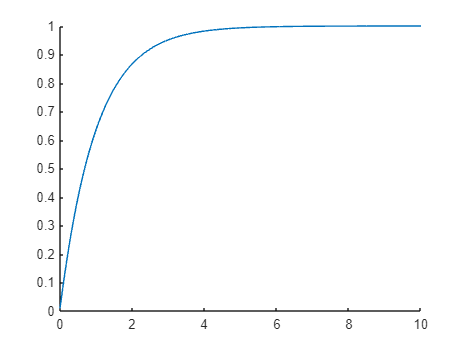

disp('THE SIZE OF THE DATA TO PLOT')
disp(size(x_history))
plot(time, x_history(1,:));